Constants_and_state_space;


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          5             456.683                        5.59e+04              1
     1         10          2.1568e-05       0.370217             12.1              1
     2         15         1.02068e-19    8.03332e-05         8.93e-07              1
     3         20         5.47999e-20    6.07159e-12         6.63e-07              1

Equation solved, inaccuracy possible.

The vector of function values is near zero, as measured by the value
of the function tolerance. However, the last step was ineffective.

<

CA_re = 2.1402e+03

CB_re = 1.0903e+03

T_re = 114.1911

Tc_re = 112.9066

A = 1.0e+03 *

   -0.0387         0   -2.6481         0
    0.0147   -0.0289    1.0063         0
    0.0001    0.0001   -0.0351    0.0308
         0         0    0.0867   -0.0867


B = 1.0e+03 *

    2.9598         0
   -1.0903         0
   -0.0093         0
         0    0.0001


C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D =      0     0
     0     0
     0     0
     0     0



Cs = [0 0 1 0; 0 0 0 1]; % only sensors in T and Tc

% Canonical form of state-space model

[X,L]=eig(A);  % T = X-1

T=inv(X);

lamba = T*A*X

lamba =  -117.8129   -0.0000    0.0000   -0.0000
   -0.0000  -37.4404    0.0000   -0.0000
   -0.0000    0.0000  -20.5155   -0.0000
   -0.0000   -0.0000    0.0000  -13.6585


Q = T*B;
Cd = C*X;
poles = eig(A)

poles =  -117.8129
  -37.4404
  -20.5155
  -13.6585



% Controllability of state-space model

Co = ctrb(A,B);
Controllability_rank = rank(Co) %the system is controllable

Controllability_rank = 4


% Observability of state-space model

Oo = obsv(A,Cs);
Observability_rank = rank(Oo)  %the system is observable without "sensors" in concentration states (matrix C)

Observability_rank = 4


% Parameters of the matrix Q and R (Rule of Bryson)

Q1 = 1/(2140)^2; 
Q2 = 100*(1/(1090)^2);
Q3 = 1/(114.2)^2;
Q4 = 100*(1/(109)^2);
R1 = 1/(35)^2; 
R2 = 1/(8500)^2; 


Qr = [Q1 0 0 0 ; 0 Q2 0 0 ; 0 0 Q3 0 ; 0 0 0 Q4] %penalize bad performance  

Qr =     0.0000         0         0         0
         0    0.0001         0         0
         0         0    0.0001         0
         0         0         0    0.0084


R = [R1 0; 0 R2] %penalize bad actuator efford

R = 1.0e-03 *

    0.8163         0
         0    0.0000



K = lqr(A,B,Qr,R) % 2 actuators (Qin/V and QH)

K =     0.0122   -0.2375   -0.6731   -0.1132
    0.8971    0.5201  296.6265  374.7840



% LQR in actuactor Qin/V:

Kin1 = K(1,1);
Kin2 = K(1,2);
Kin3 = K(1,3);
Kin4 = K(1,4);

% LQR in actuator QH:

KH1 = K(2,1);
KH2 = K(2,2);
KH3 = K(2,3);
KH4 = K(2,4);

% Matrix to reference

C_ref = [0 1 0 0;0 0 0 1];
A_cl = A - B*K;
sys_cl = ss(A_cl, B, C_ref, zeros(2,2));
Kr = inv(dcgain(sys_cl));

% Reduced Order Observer Implementation:

% The states we can measure are T and Tc (Xm)
% The states we can estimate are Ca and Cb (Xr)

% Implementation of the matrices to calcule the observer:

A11 = A(1:2,1:2);
A12 = A(1:2,3:4);
A21 = A(3:4,1:2);
A22 = A(3:4,3:4);

Bu1 = B(1:2, :);
Bu2 = B(3:4, :); 

% Implementation of the matrix of disturbances (Bd)

d = [CAin,Tin];
Bdj = jacobian(f,d);
Bd_sym = subs(Bdj,Qin_V,Qin_V_re);
Bd = double(Bd_sym);

Bd1 = Bd(1:2,:);
Bd2 = Bd(3:4, :);

% Define the observer gain matrix

sys_poles = eig(A);
Po = 2.5*sys_poles(3:4,1)

Po =   -51.2889
  -34.1463


Lt = place(A11',A21',Po)

Lt =   160.3003  -34.4747
         0         0


L = Lt'

L =   160.3003         0
  -34.4747         0


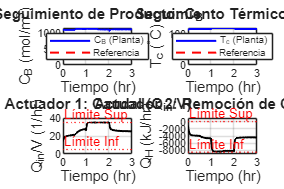


% Initializing simulation in closed loop

tmax = 3; % max time of simulation
outSim = sim("LQR_and_Observer");

t = outSim.tout;
CA = squeeze(outSim.logsout.get('CA').Values.Data);
CB = squeeze(outSim.logsout.get('CB').Values.Data);
T = squeeze(outSim.logsout.get('T').Values.Data);
Tc = squeeze(outSim.logsout.get('Tc').Values.Data);
Qin_V = squeeze(outSim.logsout.get('Qin_V').Values.Data);
QH = squeeze(outSim.logsout.get('QH').Values.Data);
CAin = squeeze(outSim.logsout.get('CAin').Values.Data);
Tin = squeeze(outSim.logsout.get('Tin').Values.Data);
CB_ref = squeeze(outSim.logsout.get('CB_ref').Values.Data);
Tc_ref = squeeze(outSim.logsout.get('Tc_ref').Values.Data);

%% --- Configuración Visual ---
lw = 1.5; % Grosor de línea principal
lw_ref = 1.5; % Grosor de línea de referencia
fs = 11; % Tamaño de fuente

%% --- FIGURA 1: Rendimiento MIMO y Actuadores (Ideal para LinkedIn) ---
figure('Name', 'Rendimiento Controlador LQR - CSTR MIMO', 'Position', [100, 100, 900, 600]);

% 1. Salida 1: Concentración de Producto (CB)
subplot(2,2,1);
plot(t, CB, 'b', 'LineWidth', lw); hold on;
plot(t, CB_ref, 'r--', 'LineWidth', lw_ref);
grid on;
title('Seguimiento de Producto: C_B', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('C_B (mol/m^3)', 'FontSize', fs);
legend('C_B (Planta)', 'Referencia', 'Location', 'best');

% 2. Salida 2: Temperatura de la Camisa (Tc)
subplot(2,2,2);
plot(t, Tc, 'b', 'LineWidth', lw); hold on;
plot(t, Tc_ref, 'r--', 'LineWidth', lw_ref);
grid on;
title('Seguimiento Térmico: T_c', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('T_c (^\circC)', 'FontSize', fs);
legend('T_c (Planta)', 'Referencia', 'Location', 'best');

% 3. Esfuerzo de Control 1: Caudal (Qin/V)
subplot(2,2,3);
plot(t, Qin_V, 'k', 'LineWidth', lw); hold on;
% Límites operativos según Klatt-Engell
yline(35, 'r:', 'Límite Sup', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left');
yline(5, 'r:', 'Límite Inf', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left');
grid on;
title('Actuador 1: Caudal (Q_{in}/V)', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('Q_{in}/V (1/hr)', 'FontSize', fs);
ylim([0, 40]);

% 4. Esfuerzo de Control 2: Remoción de Calor (QH)
subplot(2,2,4);
plot(t, QH, 'k', 'LineWidth', lw); hold on;
% Límites operativos según Klatt-Engell
yline(0, 'r:', 'Límite Sup', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left');
yline(-8500, 'r:', 'Límite Inf', 'LineWidth', 1, 'LabelHorizontalAlignment', 'left');
grid on;
title('Actuador 2: Remoción de Calor (Q_H)', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('Q_H (kJ/hr)', 'FontSize', fs);
ylim([-9000, 1000]);

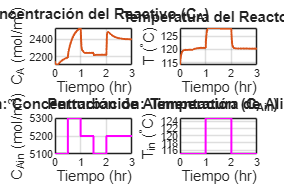


%% --- FIGURA 2: Dinámica Interna y Perturbaciones ---
figure('Name', 'Estados Secundarios y Perturbaciones', 'Position', [150, 150, 900, 600]);

% 1. Concentración del Reactivo (CA)
subplot(2,2,1);
plot(t, CA, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', lw);
grid on;
title('Concentración del Reactivo (C_A)', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('C_A (mol/m^3)', 'FontSize', fs);

% 2. Temperatura del Reactor (T)
subplot(2,2,2);
plot(t, T, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', lw);
grid on;
title('Temperatura del Reactor (T)', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('T (^\circC)', 'FontSize', fs);

% 3. Perturbación: Concentración de entrada (CAin)
subplot(2,2,3);
plot(t, CAin, 'm', 'LineWidth', lw);
grid on;
title('Perturbación: Concentración de Alimentación (C_{Ain})', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('C_{Ain} (mol/m^3)', 'FontSize', fs);

% 4. Perturbación: Temperatura de entrada (Tin)
subplot(2,2,4);
plot(t, Tin, 'm', 'LineWidth', lw);
grid on;
title('Perturbación: Temperatura de Alimentación (T_{in})', 'FontSize', fs);
xlabel('Tiempo (hr)', 'FontSize', fs);
ylabel('T_{in} (^\circC)', 'FontSize', fs);